# Calibrate phone camera from an image

Given an image taken from a camera, we use calibration tecniques to extract intrinsic and extrinsic parameters. 

In this script, we calibrate a cellphone camera using 1 of the 4 images taken.

Read the image and the pre-decided 3D points that will form the M matrix; then prepare the file output path.

imgs_folder = '../0.calib_imgs';
img_subject = 'cube';
img_filename = 'img_3';

% load the calibration image
img_folder = fullfile(imgs_folder, img_subject);
img_file = strcat(img_filename, '.jpg');
img_path = fullfile(img_folder, img_file);
calib_img = imread(img_path);

% load 3D points
calib_points_path = fullfile(img_folder, '3D-points.mat');
load(calib_points_path, 'calib_points');

% prepare result
calib_result_folder = '../0.calib_results';
[~,~,~] = mkdir(calib_result_folder);
calib_result_file = sprintf('calib-%s-%s.mat', img_subject, img_filename);
calib_result_path = fullfile(calib_result_folder, calib_result_file);

clear imgs_folder img_subject img_filename img_folder img_file img_path ...
    calib_result_folder calib_result_file calib_points_path;

Ask the user the associated 2D points in the image (in total we'll have $n$ 3D points in the $M$ matrix mapped to $n$ 2D points in the $m$ matrix). The 3D points are stored as a 4-by-$n$ matrix and the 2D points are stored as a 3-by-$n$ matrix: this choice is due to the fact that in perspective space coordinates are handy if homogeneous, thus 3D points need 4 parameters and 2D points need 3.

% calibration does not exists, begin process
if ~isfile(calib_result_path)
    % 3D points, in meters
    M = calib_points;
    n = size(M, 2);
    
    % 2D points
    m = zeros(3, n);
    
    % get images points (allow zooming in and out)
    fig = figure('Name','Select image points');
    set(gcf,'Visible','on'); % so live script will show an external figure
    imshow(calib_img), hold on;
    
    i = 1;
    while i <= n
        [u, v, b] = ginput(1);
        if isempty(b)
            break;
        elseif b == 45  % "-" key
            % zoom out
            ax = axis(); 
            width = ax(2) - ax(1); 
            height = ax(4) - ax(3);
            axis([u-width/2, u+width/2, v-height/2, v+height/2]);
            zoom(1/2);
        elseif b == 43  % "+" key
            % zoom in
            ax = axis(); 
            width = ax(2) - ax(1); 
            height = ax(4) - ax(3);
            axis([u-width/2, u+width/2, v-height/2, v+height/2]);
            zoom(2);
        else
            % add image point
            m(:,i) = [u; v; 1];
            scatter(m(1,i), m(2,i), '+r');
            i = i + 1;
        end
    end
    
    % compute calibration and project
    cal = dlt(m, M);
    cal.image = calib_img;
    save(calib_result_path, '-struct', 'cal');
    
    close(fig);
    clear m M n i u v b ax width height dyn_point calib_points fig calib_img calib_points;
end

Now that points have been collected we can adjuct the previous calibration in order to get a more accurate result.

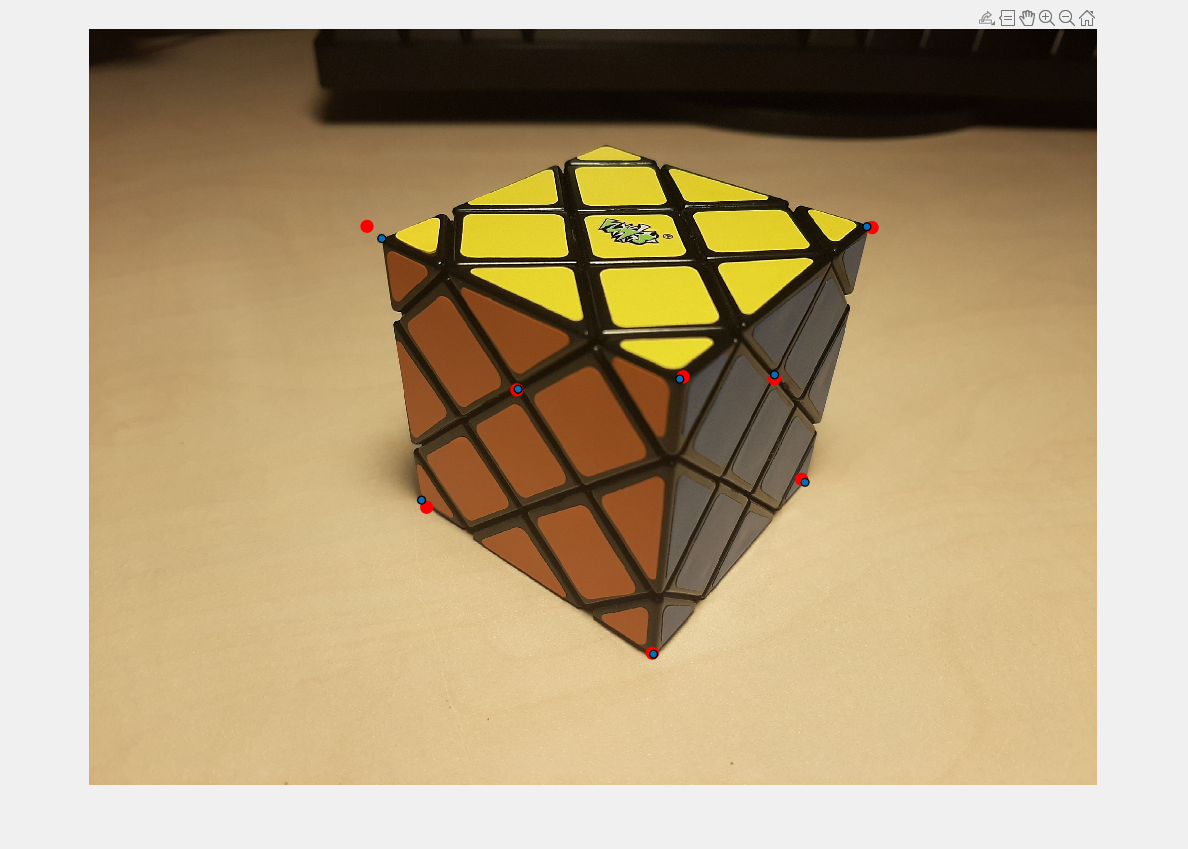

cal = load(calib_result_path);
fig = figure('Name','Adjust image points','KeyReleaseFcn', @OnKeyReleasedHandler);
set(gcf,'Visible','on'); % so live script will show an external figure
imshow(cal.image), hold on;

for i = 1:cal.n
    % create dynamic point
    dyn_point = drawpoint('Position', cal.m(1:2,i)');
    dyn_point.UserData = {i, fig};
    [~] = addlistener(dyn_point, 'ROIMoved', @OnMovedHandler);
end


% new points to project
% (we just reuse the previous points here, something else could be tested)
M_reproj = cal.M;

% prepare handles for projected points
handles_m = gobjects(0);

% give access to every point
setappdata(fig, 'handles_m', handles_m);
setappdata(fig, 'm', cal.m);
setappdata(fig, 'M', cal.M);
setappdata(fig, 'M_reproj', M_reproj);
setappdata(fig, 'image', cal.image);
setappdata(fig, 'save_path', calib_result_path);

% compute calibration and project
proj(cal, fig);


clear i dyn_point fig n_reproj M_reproj handles_m cal calib_result_path;

function OnKeyReleasedHandler(src, evt)
    if strcmp(evt.Key, 'return')
        m = getappdata(src, 'm');
        M = getappdata(src, 'M');
        
        % save final results
        cal = dlt(m, M);
        cal.image = getappdata(src, 'image');
        
        calib_result_path = getappdata(src, 'save_path');
        save(calib_result_path, '-struct', 'cal');
    end
end


function OnMovedHandler(src, ~)
    i = src.UserData{1};
    fig = src.UserData{2};
    
    % update point
    m = getappdata(fig, 'm');
    m(:,i) = [src.Position 1];
    setappdata(fig, 'm', m);
    
    % recalibrate and project
    M = getappdata(fig, 'M');
    cal = dlt(m, M);
    proj(cal, fig);
end


function proj(cal, fig)
    handles_m = getappdata(fig, 'handles_m');
    M_reproj = getappdata(fig, 'M_reproj');
    
    % reproject the calibration points
    delete(handles_m);
    m_reproj = project(cal.P, M_reproj);
    handles_m = scatter(m_reproj(1,:), m_reproj(2,:), 100, 'r', 'filled');
    setappdata(fig, 'handles_m', handles_m);
end